A. Generation of a singletone sine wave and its spectrum. 

        Generate a 10 Hz sine wave sampled at 1000 Hz sampling frequency and for a duration of 1 sec for this problem. 

fs = 1000; % Sampling frequency (samples per second) 
dt = 1/fs; % seconds per sample  
StopTime = 1; % seconds 
t = (0:dt:StopTime)'; % seconds 
F = 10; % Sine wave frequency (hertz) c
data = sin(2*pi*F*t);
figure(1);
plot(t,data) 
title('Time-Domain: A')

%%Fourier Transform:
X = fftshift(fft(data));
%%Frequency specifications:
N = size(t,1);
dF = fs/N;                      % hertz
f = -fs/2:dF:fs/2-dF;           % hertz
%%Plot the spectrum:
figure(2);
plot(f,abs(X)/N);
xlabel('Frequency (in hertz)');
title('Frequency Spectrum: A');

B. Generation of a multitone sine wave and its spectrum. 

    Generate a multitone sine wave composed of 10, 50 and 100 Hz frequency components. Use a sampling frequency of 1000Hz and a wave of duration 1 sec for the  problem.

fs = 1000; % Sampling frequency (samples per second) 
dt = 1/fs; % seconds per sample  
StopTime = 1; % seconds 
t = (0:dt:StopTime)'; % seconds 
F1 = 10; % Sine wave frequency (hertz) 
F2 = 50;
F3 = 100;
data = sin(2*pi*F1*t) + sin(2*pi*F2*t) + sin(2*pi*F3*t);
figure(3);
plot(t,data) 
title('Time-domain:B')


%%Fourier Transform:
X = fftshift(fft(data));
%%Frequency specifications:
N = size(t,1);
dF = fs/N;                      % hertz
f = -fs/2:dF:fs/2-dF;           % hertz
%%Plot the spectrum:
figure(4);
plot(f,abs(X)/N);
xlabel('Frequency (in hertz)');
title('Frequency Spectrum:B');

C. Generation of a non-stationary multitone sine wave and its spectrum

        Generate a non-stationary multitone sine wave made of different combinations of 10, 50 and 100 Hz components. Example combination: 

Sin(2𝛱*10*t)  0 < t < 0.2 sec

Sin(2𝛱*10*t) + Sin(2𝛱*50*t) 0.2 < t < 0.5 sec

Sin(2𝛱*10*t) + Sin(2𝛱*50*t) + Sin(2𝛱*100*t) 0.5 < t < 1 sec

fs = 1000; % Sampling frequency (samples per second) 
dt = 1/fs; % seconds per sample   

t1=(0:dt:0.2-dt)

t1 =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


t2=(0.2:dt:0.5-dt)

t2 =     0.2000    0.2010    0.2020    0.2030    0.2040    0.2050    0.2060    0.2070    0.2080    0.2090    0.2100    0.2110    0.2120    0.2130    0.2140    0.2150    0.2160    0.2170    0.2180    0.2190    0.2200    0.2210    0.2220    0.2230    0.2240    0.2250    0.2260    0.2270    0.2280    0.2290    0.2300    0.2310    0.2320    0.2330    0.2340    0.2350    0.2360    0.2370    0.2380    0.2390    0.2400    0.2410    0.2420    0.2430    0.2440    0.2450    0.2460    0.2470    0.2480    0.2490


t3=(0.5:dt:1-dt)

t3 =     0.5000    0.5010    0.5020    0.5030    0.5040    0.5050    0.5060    0.5070    0.5080    0.5090    0.5100    0.5110    0.5120    0.5130    0.5140    0.5150    0.5160    0.5170    0.5180    0.5190    0.5200    0.5210    0.5220    0.5230    0.5240    0.5250    0.5260    0.5270    0.5280    0.5290    0.5300    0.5310    0.5320    0.5330    0.5340    0.5350    0.5360    0.5370    0.5380    0.5390    0.5400    0.5410    0.5420    0.5430    0.5440    0.5450    0.5460    0.5470    0.5480    0.5490


data1 = sin(2*pi*F1*t1)

data1 =          0    0.0628    0.1253    0.1874    0.2487    0.3090    0.3681    0.4258    0.4818    0.5358    0.5878    0.6374    0.6845    0.7290    0.7705    0.8090    0.8443    0.8763    0.9048    0.9298    0.9511    0.9686    0.9823    0.9921    0.9980    1.0000    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628


data2=sin(2*pi*F1*t2)+sin(2*pi*F2*t2)

data2 =     0.0000    0.3718    0.7131    0.9964    1.1997    1.3090    1.3192    1.2348    1.0695    0.8448    0.5878    0.3284    0.0968   -0.0800   -0.1805   -0.1910   -0.1067    0.0673    0.3170    0.6208    0.9511    1.2776    1.5701    1.8011    1.9491    2.0000    1.9491    1.8011    1.5701    1.2776    0.9511    0.6208    0.3170    0.0673   -0.1067   -0.1910   -0.1805   -0.0800    0.0968    0.3284    0.5878    0.8448    1.0695    1.2348    1.3192    1.3090    1.1997    0.9964    0.7131    0.3718


data3=sin(2*pi*F1*t3)+sin(2*pi*F2*t3)+sin(2*pi*F3*t3)

data3 =     0.0000    0.9596    1.6642    1.9475    1.7875    1.3090    0.7314    0.2837    0.1185    0.2571    0.5878    0.9162    1.0478    0.8710    0.4072   -0.1910   -0.6945   -0.8838   -0.6340    0.0330    0.9511    1.8654    2.5211    2.7522    2.5369    2.0000    1.3613    0.8501    0.6190    0.6898    0.9511    1.2085    1.2681    1.0183    0.4811   -0.1910   -0.7683   -1.0311   -0.8543   -0.2594    0.5878    1.4326    2.0206    2.1859    1.9070    1.3090    0.6120    0.0453   -0.2379   -0.2160


data = []


data =

     []



data=[data data1]

data =          0    0.0628    0.1253    0.1874    0.2487    0.3090    0.3681    0.4258    0.4818    0.5358    0.5878    0.6374    0.6845    0.7290    0.7705    0.8090    0.8443    0.8763    0.9048    0.9298    0.9511    0.9686    0.9823    0.9921    0.9980    1.0000    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628


data = [data data2]

data =          0    0.0628    0.1253    0.1874    0.2487    0.3090    0.3681    0.4258    0.4818    0.5358    0.5878    0.6374    0.6845    0.7290    0.7705    0.8090    0.8443    0.8763    0.9048    0.9298    0.9511    0.9686    0.9823    0.9921    0.9980    1.0000    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628


data = [data data3]

data =          0    0.0628    0.1253    0.1874    0.2487    0.3090    0.3681    0.4258    0.4818    0.5358    0.5878    0.6374    0.6845    0.7290    0.7705    0.8090    0.8443    0.8763    0.9048    0.9298    0.9511    0.9686    0.9823    0.9921    0.9980    1.0000    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628


figure(5);
plot(data);

title('Time-domain :C : Full Signal')

%%Fourier Transform:
X = fftshift(fft(data));
%%Frequency specifications:
N = size(t,1);
dF = fs/N;                      % hertz
f = -fs/2:dF:fs/2-dF;           % hertz
%%Plot the spectrum:
figure(6);
plot(abs(X)/N);

xlabel('Frequency');
title('Frequency Spectrum : C : Full signal');

% Seperate Stationary Functions

%%Fourier Transform:
X1 = fftshift(fft(data1));
%%Frequency specifications:
N1 = size(t1,1);
dF1 = fs/N1;                      % hertz
f = -fs/2:dF1:fs/2-dF1;           % hertz
%%Plot the spectrum:
figure(7);
plot(abs(X1)/N1);
xlabel('Frequency');
title('Frequency Spectrum : C : Data1');


%%Fourier Transform:
X1 = fftshift(fft(data2));
%%Frequency specifications:
N1 = size(t2,1);
dF1 = fs/N1;                      % hertz
f = -fs/2:dF1:fs/2-dF1;           % hertz
%%Plot the spectrum:
figure(8);
plot(abs(X1)/N1);
xlabel('Frequency');
title('Frequency Spectrum : C : Data2');

%%Fourier Transform:
X1 = fftshift(fft(data3));
%%Frequency specifications:
N1 = size(t3,1);
dF1 = fs/N1;                      % hertz
f = -fs/2:dF1:fs/2-dF1;           % hertz
%%Plot the spectrum:
figure(9);
plot(abs(X1)/N1);
xlabel('Frequency');
title('Frequency Spectrum : C : Data3');

`Observation:`

`The peak of frequency decreases as the frequency components increase.`

`The frequency components are sharper in individual stationary signals, whereas they spread out in the whole signal taken together.`

`Limitation of FFT:`` The frequency change w.r.t time is not depicted.`

D. 

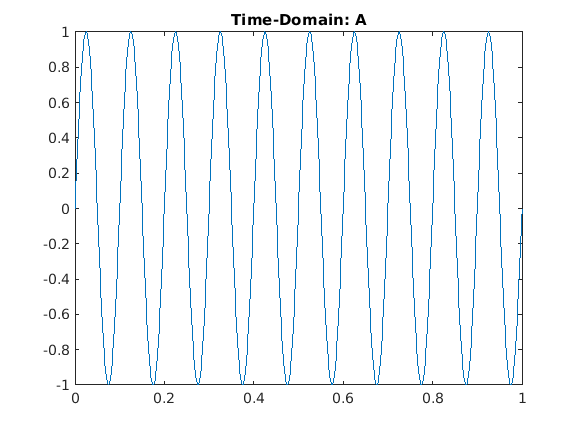

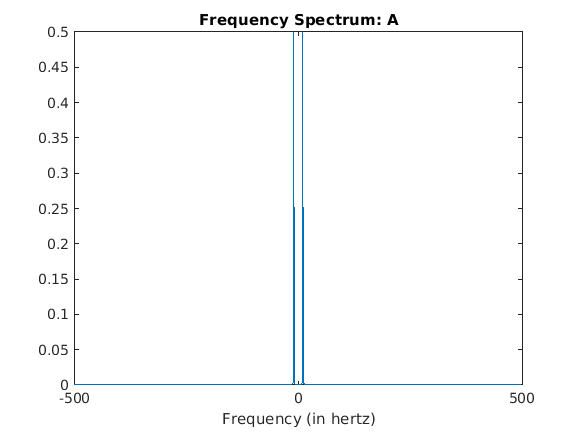

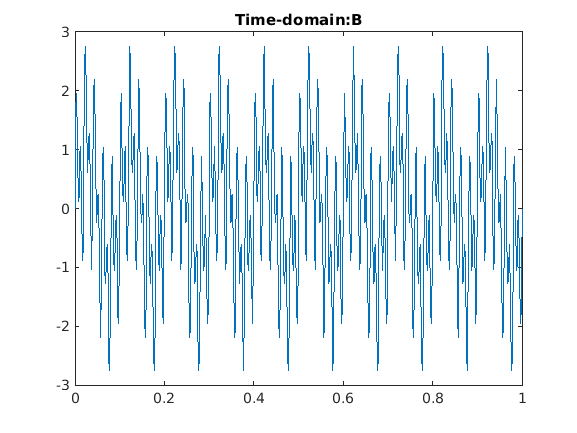

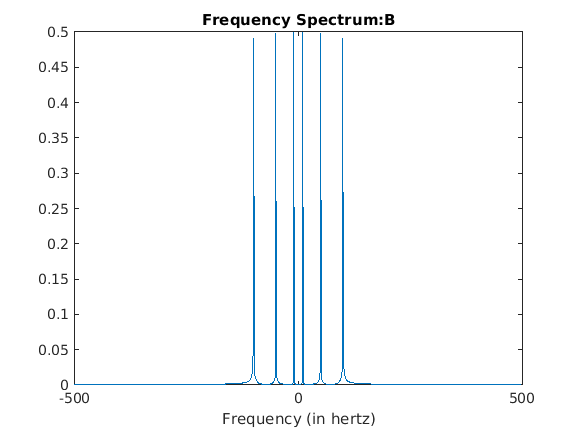

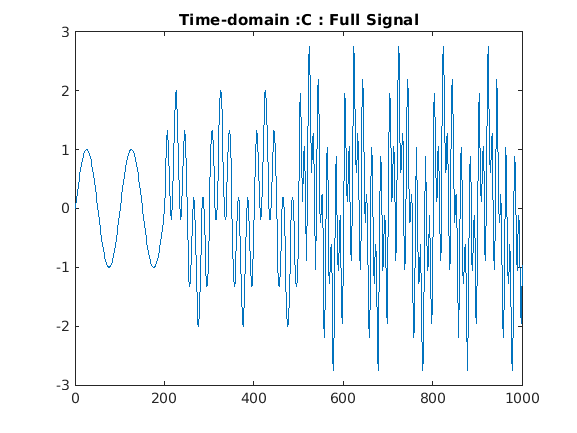

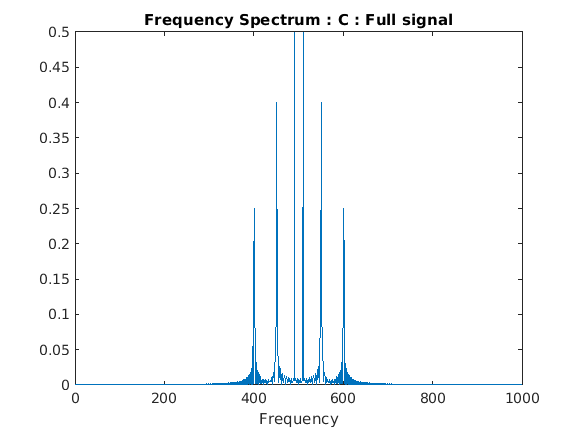

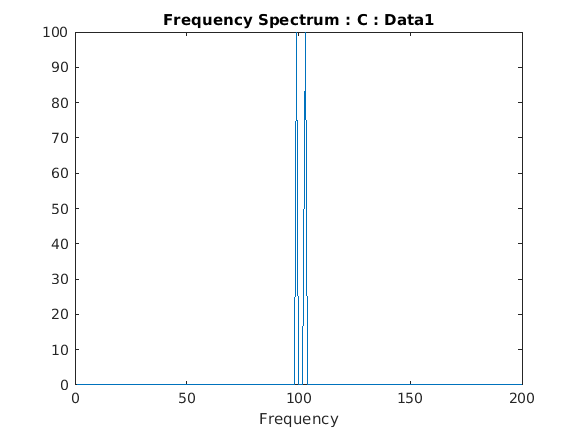

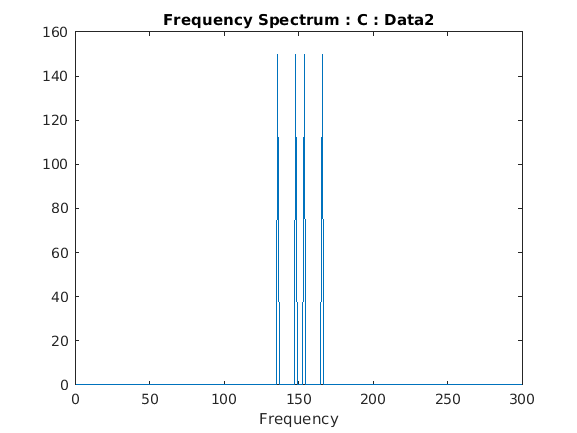


[y,Fs] = audioread('Sakshat_Speech_Processing.wav');
sound(y,Fs);   

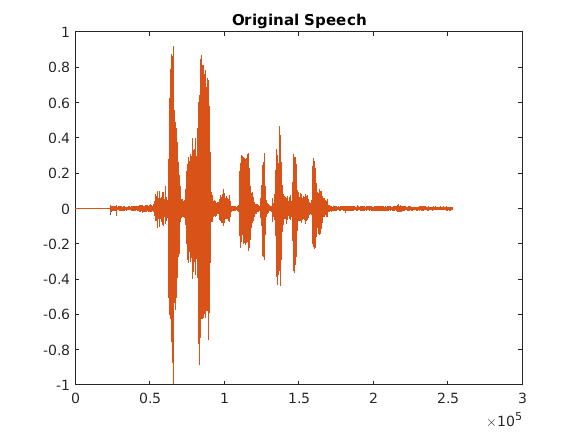

t = (1:length(y))/Fs;                 % Time Duration
ynew=resample(y,8000,Fs);              % Resampling the speech signal at 8kHz 
t = (1:length(y))/8000;                  % Time Duration after Resampling

figure(10);
plot(y);
title('Original Speech')

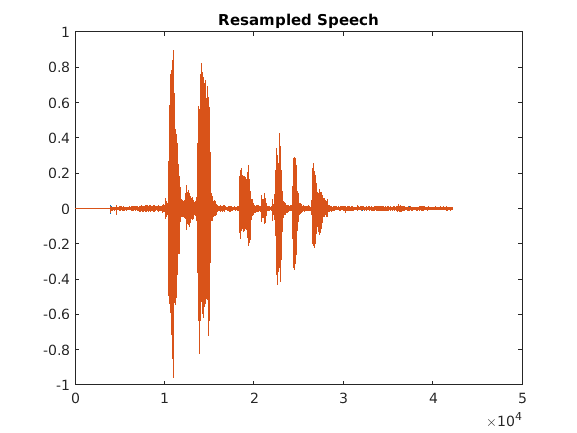

figure(11);
plot(ynew);
title('Resampled Speech')

fs = 8000  %new resampled frequencies

fs = 8000

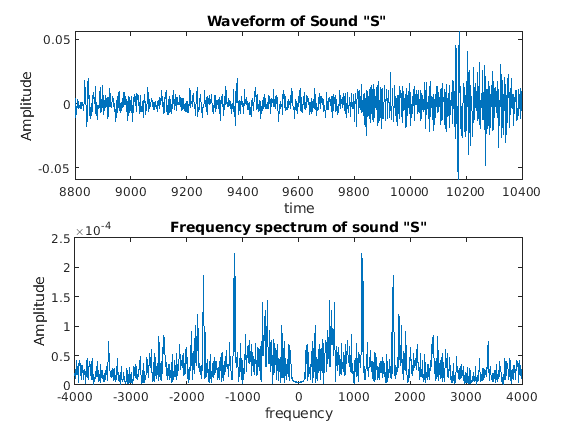


%% Sound: 'S'
t1=1.100*fs : 1.300*fs    ;           % Time Observed From Wavesurfer
x1=ynew(t1);                             
dF1= fs/length(t1);                   % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ;               % hz pers sample
X1=fftshift(fft(x1));                 % Fourier transform
figure(12);
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "S" ');
subplot(2,1,2);
plot(f1,abs(X1)/fs);
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "S"');

`Observation:`

`‘S’ is fricative and unvoiced sound. The amplitude is low and there is some blockage in speaking.`

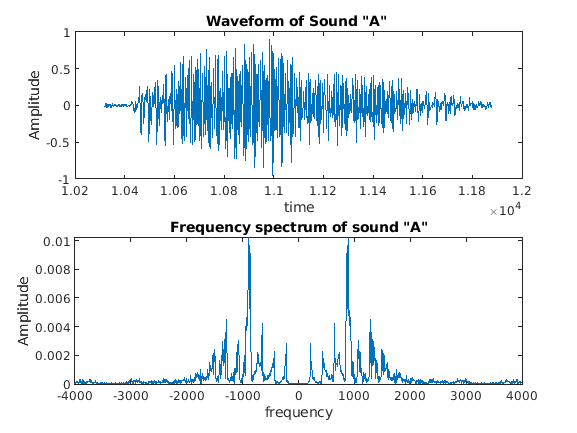

%% Sound: 'a'
t1=1.290*fs : 1.485*fs    ;           % Time Observed From Wavesurfer
x1=ynew(t1);                             
dF1= fs/length(t1);                   % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ;               % hz pers sample
X1=fftshift(fft(x1));                 % Fourier transform
figure(13);
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "A" ');
subplot(2,1,2);
plot(f1,abs(X1)/fs);
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "A"');

`Observation:`

`‘A’ is vowel and voiced sound. It is periodic in nature.Amplitude is high.`

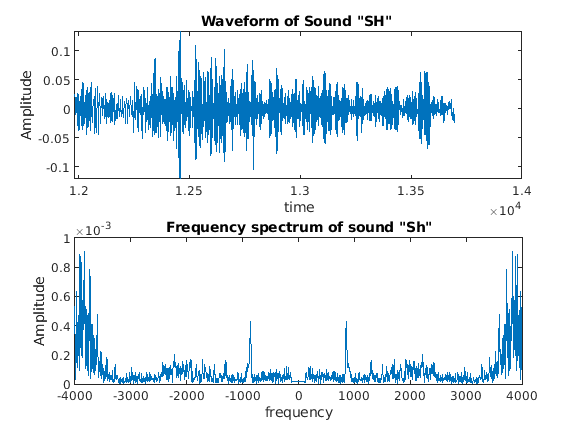

%% Sound: 'sh'
t1=1.498*fs : 1.712*fs    ;           % Time Observed From Wavesurfer
x1=ynew(t1);                             
dF1= fs/length(t1);                   
f1=-fs/2:dF1:fs/2-dF1 ;               % hz pers sample
X1=fftshift(fft(x1));                 % Fourier transform
figure(14);
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "SH" ');
subplot(2,1,2);
plot(f1,abs(X1)/fs);
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "Sh"');

`Observation:`

`‘Sh’ is fricative and unvoiced sound. The amplitude is low and there is some blockage in speaking.`

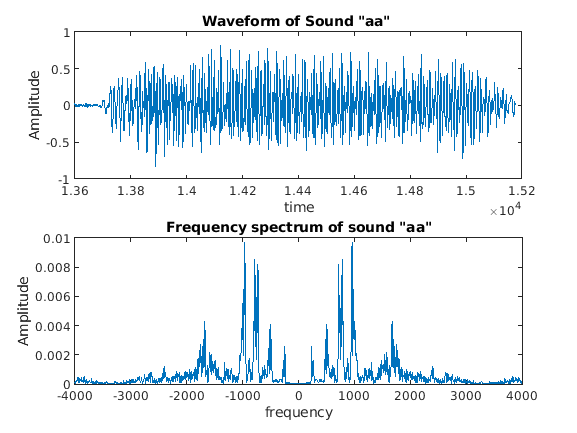

%% Sound: 'aa'
t1=1.700*fs : 1.897*fs    ;           % Time Observed From Wavesurfer
x1=ynew(t1);                             
dF1= fs/length(t1);                   
f1=-fs/2:dF1:fs/2-dF1 ;               % hz pers sample
X1=fftshift(fft(x1));                 % Fourier transform
figure(15);
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "aa" ');
subplot(2,1,2);
plot(f1,abs(X1)/fs);
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "aa"');

`Observation:`

`‘aa’ is a vowel and voiced sound. It is periodic in nature and amplitude is high.`

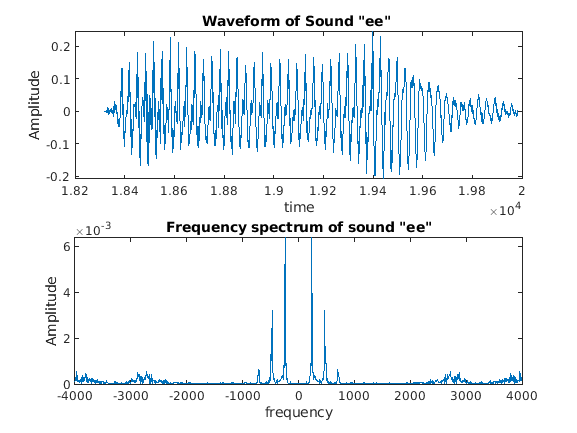

%% Sound: 'ee'
t1=2.290*fs : 2.498*fs    ;           % Time Observed From Wavesurfer
x1=ynew(t1);                             
dF1= fs/length(t1);                   
f1=-fs/2:dF1:fs/2-dF1 ;               % hz pers sample
X1=fftshift(fft(x1));                 % Fourier transform
figure(16);
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "ee" ');
subplot(2,1,2);
plot(f1,abs(X1)/fs);
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "ee"');

`Observation:`

`‘ee’ is a vowel and voiced sound. It is periodic in nature and amplitude is high`

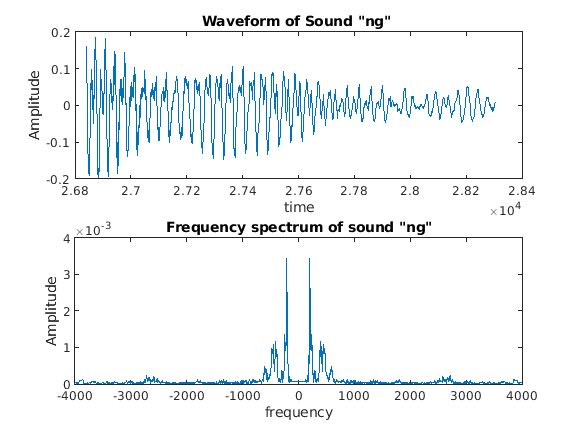

%% Sound: 'ng'
t1=3.355*fs : 3.538*fs    ;           % Time Observed From Wavesurfer
x1=ynew(t1);                             
dF1= fs/length(t1);                   
f1=-fs/2:dF1:fs/2-dF1 ;               % hz pers sample
X1=fftshift(fft(x1));                 % Fourier transform
figure(17);
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "ng" ');
subplot(2,1,2);
plot(f1,abs(X1)/fs);
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "ng"');

`Ng’ is a nasal sound.Some resistance is observed in air flow.`

`Other Observations:`

`Based on observations above, `

- `Amplitudes comparison in descending order: vowel>Nasals>stop constant >fricatives.`

- `Voiced sounds are found to have max amplitudes and hence they have max energy.`

- `The whole-speech signal is non-stationary in nature.`

- `Voiced have less ZCR than unvoiced. `